# Hodgkin-Huxley Extended Model

## Background

The Hodgkin-Huxley (HH) model is a system of differential equations that is used to simulate a neuronal action potential (AP).

The model assumes Na and K voltage-gated channels are responsible for the non-linear AP. A passive leak channel is added to account for unknown currents that contribute to the AP. The membrane acts like a capacitor and the capacitive current must also be accounted for.

The diagram below shows the HH model in an equivalent circuit diagram. 

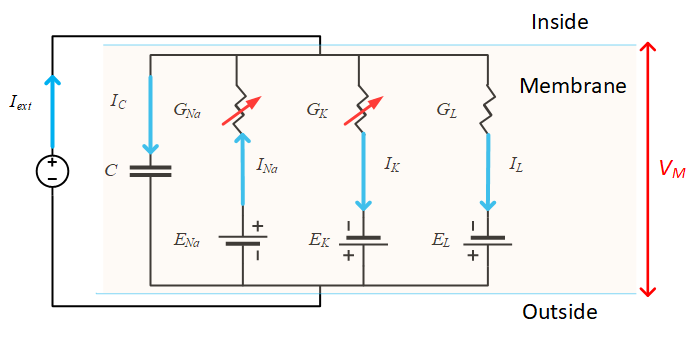

This interactive program implements the original Hodgkin-Huxley neuron model with 2 different types of voltage-gated Ca channel (VGCC) added. The VGCC's are similar to the Na and K voltage-gated channels. However, one VGCC is activated at low membrane potential changes and one is activated at high changes.

The diagram below shows the extended HH model in an equivalent circuit diagram. 

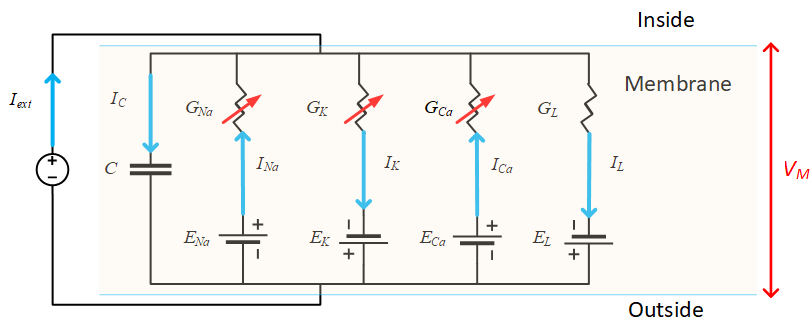

Vrest       = -70; % mV 
dt          = 0.01; % ms
totalTime   = 180; % ms
startStim   = 50; % ms
endStim     = 150; % ms
startStim   = startStim / dt;
endStim     = endStim / dt;
t           = 0:dt:totalTime; % Vector of timesteps
%unit: uA/cm^2
I_ext = 2; 
vgcc = 1; 
% Constants
C       = 1; % uF/cm^2
E_Na    = 115 + Vrest; % mV
E_K     = -6 + Vrest; %mV
E_Leak  = 10.6 + Vrest; % mV
E_Ca    = 137; % mV
g_Na    = 120; % mS/cm^2
g_K     = 36; % mS/cm^2
g_Leak  = 0.3; % mS/cm^2
g_Ca    = 1; % mS/cm^2; Ref: doi: 10.3389/fncel.2015.00047
% I_ext   = 13; % uA/cm^2
%% Initializing values
% Current input
%    ==> change this to see how different inputs affect the neuron
I_current = zeros(1,length(t));
I_current(startStim:endStim) = I_ext; % Input of 3 microA/cm2 beginning at 50 ms and steady until end of time period.
% Preallocating variables
temp = zeros(1,length(t));
V = temp;
m = temp;
n = temp;
h = temp;
r = temp;
mca = temp;
G_K = temp;
G_Na = temp;
conductance_Ca = temp;
I_Na = temp;
I_K = temp;
I_Ca = temp;
I_Leak = temp;
V(1) = Vrest; % membrane potential is starting at its resting state
% Separate functions to get the alpha and beta values
[alphaM, betaM] = m_equations(V(1), Vrest);
[alphaN, betaN] = n_equations(V(1), Vrest);
[alphaH, betaH] = h_equations(V(1), Vrest);
[m_inf, tau_m] = mca_equations(V(1));
% Initializing gating variables to the asymptotic values 
%  when membrane potential is set to the membrane resting value
m(1) = (alphaM / (alphaM + betaM));
n(1) = (alphaN / (alphaN + betaN));
h(1) = (alphaH / (alphaH + betaH));
mca(1) = m_inf;
% Start simulation
for i = 1:length(t)-1 
    % Calculate new alpha and beta based on last known membrane potential
    [alphaN, betaN] = n_equations(V(i), Vrest);
    [alphaM, betaM] = m_equations(V(i), Vrest);
    [alphaH, betaH] = h_equations(V(i), Vrest);
    % Conductance variables  
    % %(computed separately to show how this changes with membrane potential)
    G_K(i) = g_K*(n(i)^4);
    G_Na(i)=g_Na*(m(i)^3)*h(i);
    if vgcc == 1
        r(i) = r_equation(V(i));
        conductance_Ca(i)=g_Ca*r(i);
    elseif vgcc == 2
        [m_inf, tau_m] = mca_equations(V(i));
        conductance_Ca(i)=g_Ca*mca(i)^3;
        mca(i+1) = mca(i) + ((m_inf - mca(i))/tau_m) * dt;
    end
    % Calculating ionic currents
    I_Na(i) = G_Na(i)*(V(i)-E_Na);
    I_K(i) = G_K(i)*(V(i)-E_K);
    I_Leak(i) = g_Leak*(V(i)-E_Leak);
    I_Ca(i) = conductance_Ca(i) * (V(i)-E_Ca);
    % Calculating the total input
    Input = I_current(i) - (I_Na(i) + I_K(i) + I_Leak(i));
    % Calculating the new membrane potential
    V(i+1) = V(i) + Input* dt*(1/C);
    % Calculating new values for the gating variables
    m(i+1) = m(i) + (alphaM *(1-m(i)) - betaM * m(i))*dt;
    n(i+1) = n(i) + (alphaN *(1-n(i)) - betaN * n(i))*dt;
    h(i+1) = h(i) + (alphaH *(1-h(i)) - betaH * h(i))*dt;
end

## Results

%% Plot Results
amp = 0.01; % Conversion factor to convert from uA/cm^2 to A/m^2
siemen = 10; % Conversion factor to convert from mS/cm^2 to S/m^2

### Membrane potential

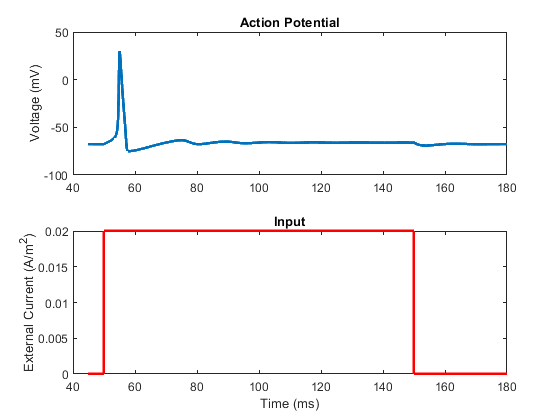

% Plot membrane potential
% figure('Name', 'Membrane Potential vs input')
% subplot(2,1,1)
% plot(t,V)
% ylabel('V_m (mV)')
% title('Action Potential')
% subplot(2,1,2)
% plot(t,I_current*amp, 'r')
% xlabel('Time (ms)')
% ylabel('External Current (A/m^2)')
% title('Input')


figure('Name', 'Membrane Potential vs input')
subplot(2,1,1)
plot(t(45/dt:end),V(45/dt:end), 'LineWidth', 2)
ylabel('Voltage (mV)')
title('Action Potential')
subplot(2,1,2)
plot(t(45/dt:end),I_current(45/dt:end)*amp, 'r', 'LineWidth', 2)
xlabel('Time (ms)')
ylabel('External Current (A/m^2)')
title('Input')

### Currents

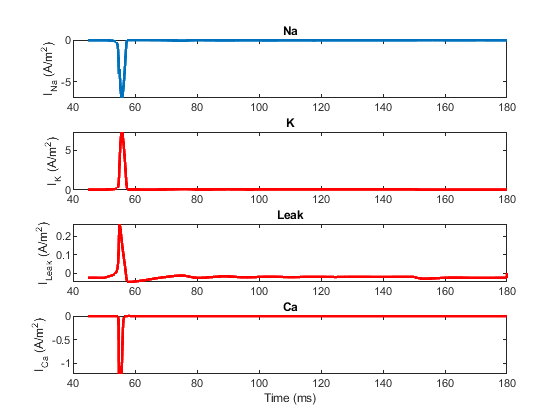

figure('Name', 'Currents')
subplot(4,1,1)
plot(t(45/dt:end),I_Na(45/dt:end)*amp, 'LineWidth', 2)
ylabel('I_{Na} (A/m^2)')
title('Na')
subplot(4,1,2)
plot(t(45/dt:end),I_K(45/dt:end)*amp, 'r', 'LineWidth', 2)
ylabel('I_{K} (A/m^2)')
title('K')
subplot(4,1,3)
plot(t(45/dt:end),I_Leak(45/dt:end)*amp, 'r', 'LineWidth', 2)
ylabel('I_{Leak} (A/m^2)')
title('Leak')
subplot(4,1,4)
plot(t(45/dt:end),I_Ca(45/dt:end)*amp, 'r', 'LineWidth', 2)
xlabel('Time (ms)')
ylabel('I_{Ca} (A/m^2)')
title('Ca')

### Conductances

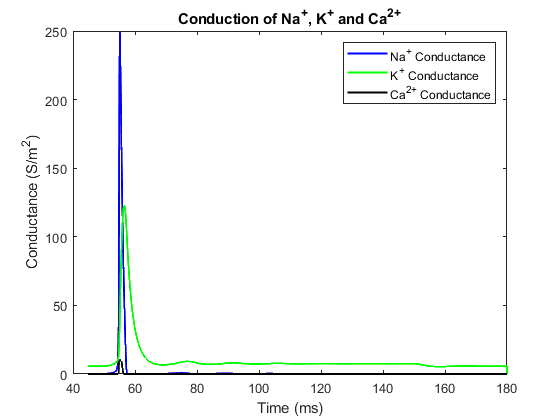

figure('Name', 'Conductance');
plot(t(45/dt:end), G_Na(45/dt:end)*siemen, 'b', t(45/dt:end), G_K(45/dt:end)*siemen, 'g', t(45/dt:end), conductance_Ca(45/dt:end)*siemen, 'k', 'LineWidth', 1.5)
legend('Na^+ Conductance', 'K^+ Conductance', 'Ca^{2+} Conductance')
xlabel('Time (ms)')
ylabel('Conductance (S/m^2)')
title('Conduction of Na^+, K^+ and Ca^{2+}')

### Gating variables

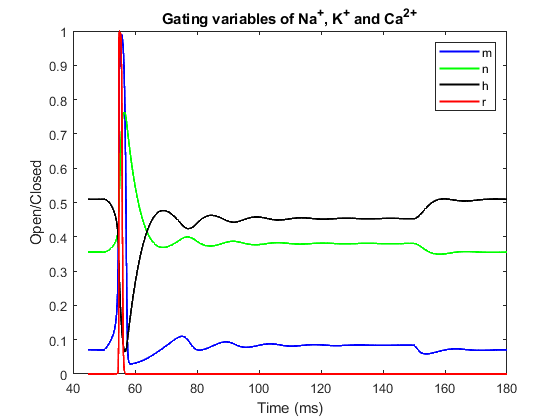

figure('Name', 'Gating Variables');
plot(t(45/dt:end), m(45/dt:end), 'b', t(45/dt:end), n(45/dt:end), 'g', t(45/dt:end), h(45/dt:end), 'k', 'LineWidth', 1.5)
xlabel('Time (ms)')
ylabel('Open/Closed')
title('Gating variables of Na^+, K^+ and Ca^{2+}')
hold on
if vgcc == 1
    plot(t(45/dt:end), r(45/dt:end), 'r', 'LineWidth', 1.5)
    legend('m', 'n', 'h', 'r')
elseif vgcc == 2
    plot(t(45/dt:end), mca(45/dt:end), 'r', 'LineWidth', 1.5)
    legend('m', 'n', 'h', 'mca')
end

%% Helper Functions

% Calculate alpha m and beta m for Na activation

function [alpha_m, beta_m] = m_equations(V, Vrest)
alpha_m = (2.5-0.1*(V-Vrest))/(exp(2.5-0.1*(V-Vrest))-1);
beta_m = 4*exp((Vrest-V)/18);
end 
% Calculate alpha n and beta n for K activation
function [alpha_n, beta_n] = n_equations(V, Vrest)
alpha_n = (0.1-0.01*(V-Vrest))/(exp(1-0.1*(V-Vrest))-1);
beta_n = 0.125*exp((Vrest-V)/80);
end
% calculate alpha h and beta h for Na inactivation
function [alpha_h, beta_h] = h_equations(V, Vrest)
alpha_h = 0.07*exp((Vrest-V)/20);
beta_h = 1/(1+exp(3-0.1*(V-Vrest)));
end
% Calculate gating variable for Ca VGCC1 activation
function [r] = r_equation(V)
% params
Vh = -10; % voltage at which gCa is half; unit: mV;
k = -6; % Slope factor for VGCC; unit: mV
% gating
r = 1 / (1 + exp((V - Vh) / k));
end
% calculate m_inf and tau_m for Ca VGCC2 activation
function [m_inf, tau_m] = mca_equations(V)
m_inf = 1 / (1 + exp(-((V+24.758)/8.429)));
if V >= -40
    tau_m = 0.2702+1.1622*exp(-(V+22.098)^2/164.19);
else
    tau_m = 0.6923*exp((V-4.7)/1089.372);
end
end
